# Lab 2 - LUT Transforms and Histogram Operations

Nick Snyder

## Part 1: Getting Familiar with LUTs

esc = rgb2gray(imread('esc.jpg'));

**2.**

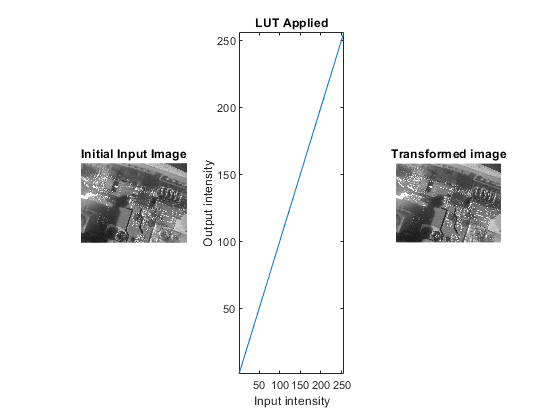

Ii = 0:255;
Io = Ii;                                            
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image'); 

**3.**

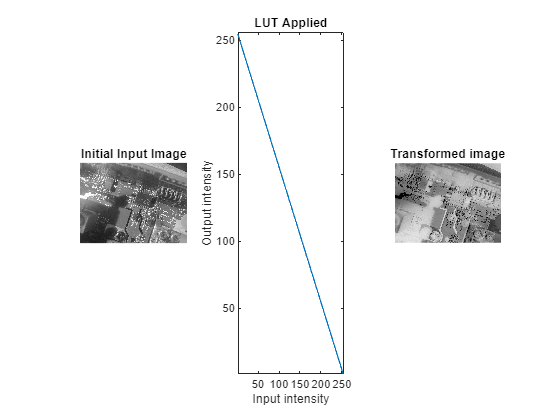

Ii = 0:255;
Io = 255 - Ii;                                           
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image'); 

**4.**

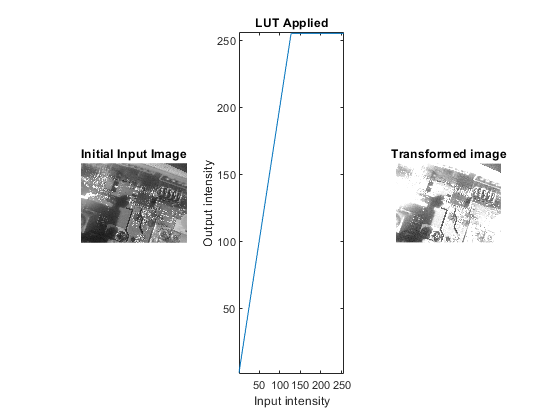

Ii = 0 : 255;
Io = Ii;
Io(1:128) = Ii(1:128) * 2;  Io(129:256) = 255;
colormap = [Io' Io' Io'] / 255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image'); 

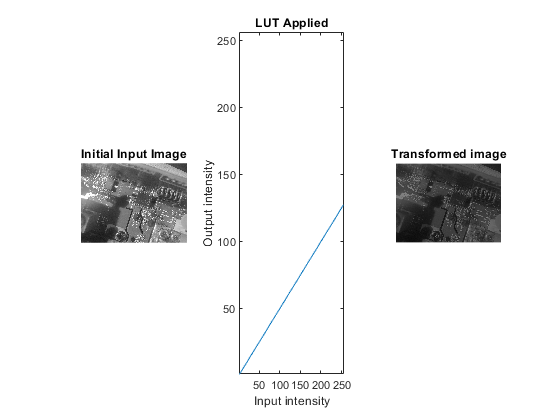

Ii = 0:255;
Io = floor(Ii/2);
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image'); 

**5.**

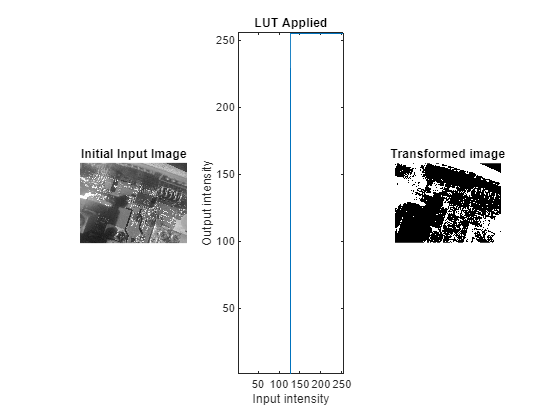

Ii = 0:255;
Io = Ii;
Io(1:128)=0; Io(129:256)=255;
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image');

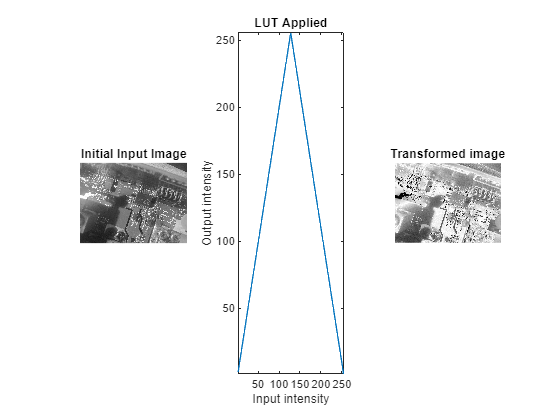

Ii = 0:255;
Io = Ii;
Io(1:128)=Ii(1:128)*2; Io(129:256)=255-Ii(1:128)*2;
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(esc), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(esc, colormap), title('Transformed image');

The LUT is very versitile and can be used to change brightness, bit depth, and invert images.

## Part 2: User-Defined LUTs

**1.**

gramp = rgb2gray(imread('gramp.jpg'));

**2.**

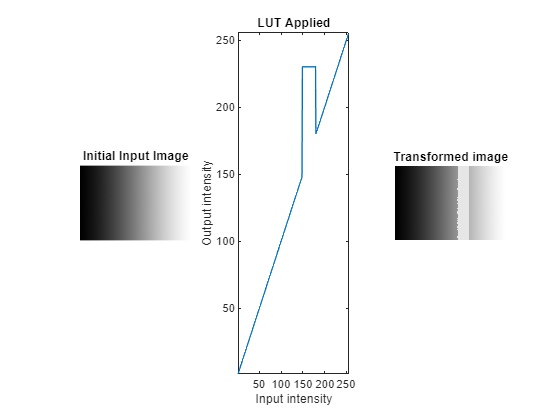

Ii = 0:255;
Io = Ii;
Io(150:180) = 230;
colormap = [Io' Io' Io']/255;
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(gramp, colormap), title('Transformed image');

The highlighted band is clearly visible

**3.**

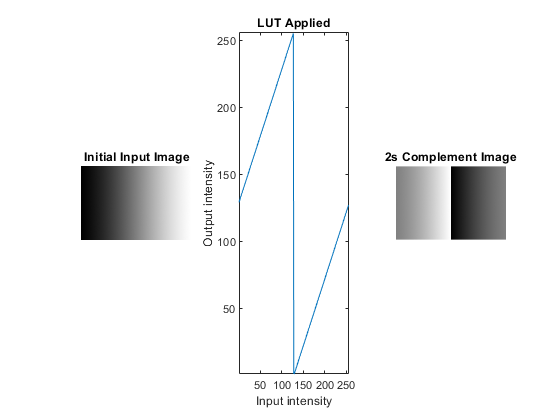

LUT = uint8(zeros([1 256]));
LUT(1:128) = Ii(1:128) + 128;
LUT(129:256) = Ii(129:256) - 128;
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, LUT), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(intlut(gramp, LUT)), title('2s Complement Image');

The 2s complement shifts the normal LUT by half a period which appears as the image is split in half.

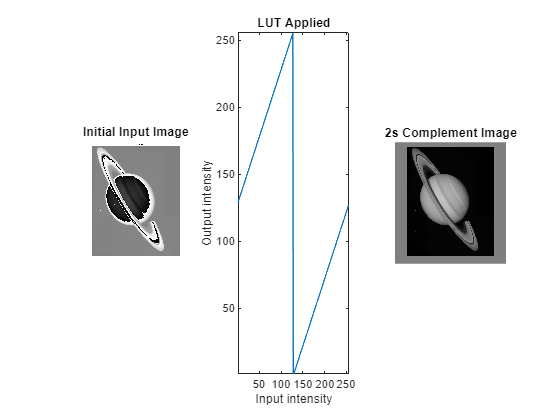

test = rgb2gray(imread('TEST.png'));
LUT = uint8(zeros([1 256]));
LUT(1:128) = Ii(1:128) + 128;
LUT(129:256) = Ii(129:256) - 128;
figure
subplot(1, 3, 1), imshow(test), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, LUT), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(intlut(test, LUT)), title('2s Complement Image');

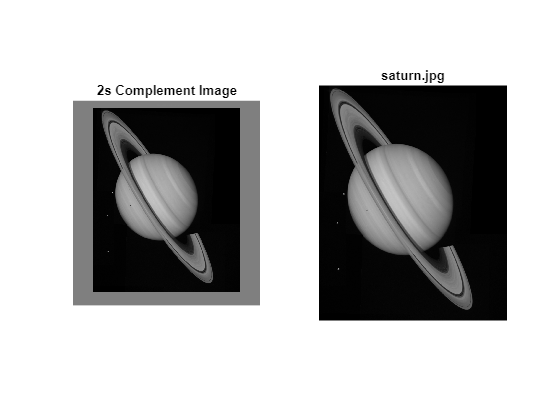

figure
subplot(1, 2, 1), imshow(intlut(test, LUT)), title('2s Complement Image'); 
subplot(1, 2, 2), imshow(rgb2gray(imread('saturn.png'))), title('saturn.jpg');

The test image seems to be the 2s complement of the saturn image thus taking the 2s complement again shows the normal image.

**4.**

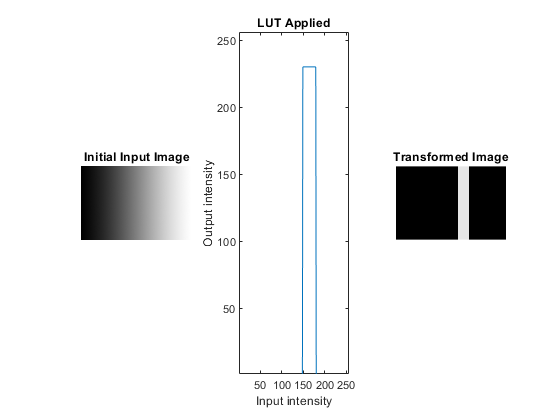

gramp = rgb2gray(imread('gramp.jpg'));
Io(1:256) = 0;   
Io(150:180) = 230;
colormap = [Io' Io' Io'] / 255; 
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(gramp, colormap), title('Transformed Image');

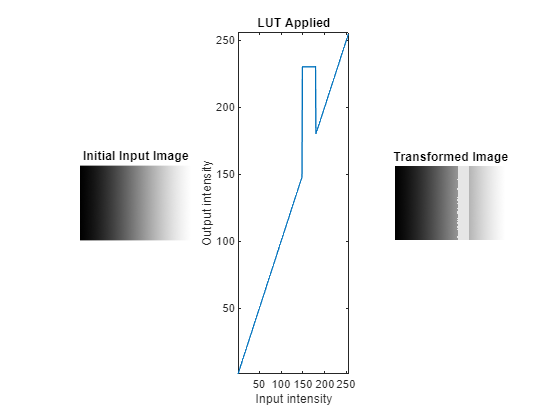

Io = Ii;   
Io(150:180) = 230;
colormap = [Io' Io' Io'] / 255; 
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(gramp, colormap), title('Transformed Image');

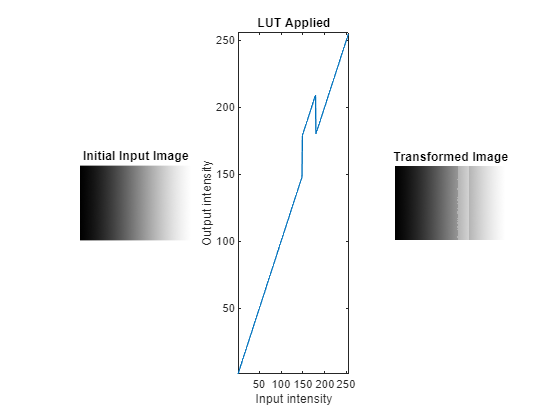

Io = Ii;   
Io(150:180) = Io(150:180) + 30;
colormap = [Io' Io' Io'] / 255; 
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(gramp, colormap), title('Transformed Image');

**5.**

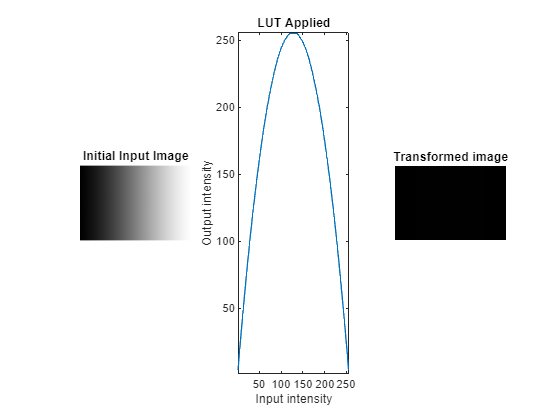

Io = -(1 / 64) * (Ii .^ 2) + (4 * Ii);                      
Io = uint8(Io);
colormap = [Io' Io' Io'] / 255;
figure
subplot(1, 3, 1), imshow(gramp), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, Io), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity'), 
subplot(1, 3, 3), imshow(gramp, colormap), title('Transformed image');

Not sure why the colormap is acting weird here but it is all zeros. With the quadratic I made, it should show the middle as white and both the left and right as black.

**6.**

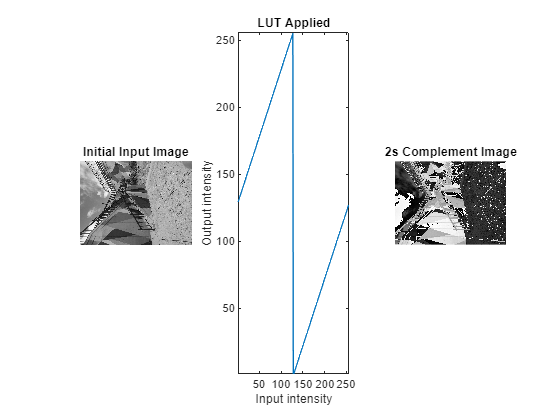

stairs = rgb2gray(imread('stairs.jpg'));
LUT = uint8(zeros([1 256]));
LUT(1:128) = Ii(1:128) + 128;
LUT(129:256) = Ii(129:256) - 128;
figure
subplot(1, 3, 1), imshow(stairs), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, LUT), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(intlut(stairs, LUT)), title('2s Complement Image');

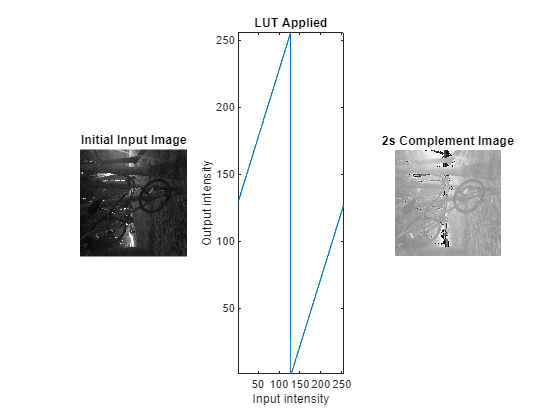

tree = rgb2gray(imread('tree.jpg'));
LUT = uint8(zeros([1 256]));
LUT(1:128) = Ii(1:128) + 128;
LUT(129:256) = Ii(129:256) - 128;
figure
subplot(1, 3, 1), imshow(tree), title('Initial Input Image'); 
subplot(1, 3, 2), plot(Ii, LUT), axis([ 1 256 1 256 ]), title('LUT Applied'), xlabel('Input intensity'), ylabel('Output intensity');
subplot(1, 3, 3), imshow(intlut(tree, LUT)), title('2s Complement Image');

**7.**

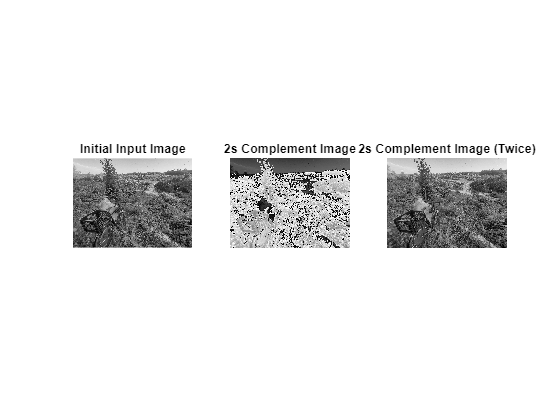

copenhagen = rgb2gray(imread('copenhagen.jpg'));
LUT = uint8(zeros([1 256]));
LUT(1:128) = Ii(1:128) + 128;
LUT(129:256) = Ii(129:256) - 128;
figure
subplot(1, 3, 1), imshow(copenhagen), title('Initial Input Image'); 
subplot(1, 3, 2), imshow(intlut(copenhagen, LUT)), title('2s Complement Image');
subplot(1, 3, 3), imshow(intlut(intlut(copenhagen, LUT), LUT)), title('2s Complement Image (Twice)');

The initial image and the image which 2s complement was applied twice appear equivalent as expected. This is because the 2s complement essentially shifts the LUT half a period which means doing it twice would shift the LUT a whole period. That is the same as the original LUT.

## Part 3: Histogram Operations

**2.**

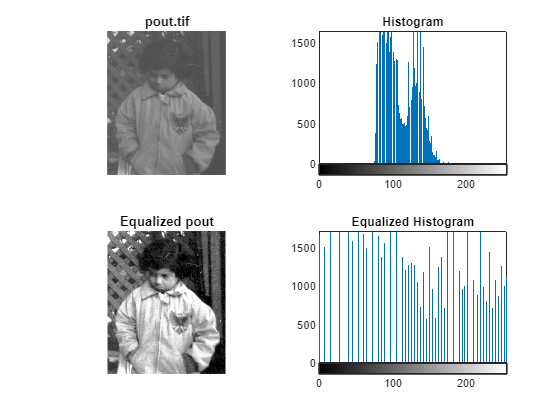

pout = imread('pout.tif');
figure
subplot(2,2,1), imshow(pout), title('pout.tif');
subplot(2,2,2), imhist(pout), title('Histogram');
subplot(2,2,3), imshow(histeq(pout)), title('Equalized pout');
subplot(2,2,4), imhist(histeq(pout)), title('Equalized Histogram');

Pout.tif looks the best because the original histogram is focused towards the middle and the equalization spreads it out evenly in both directions.

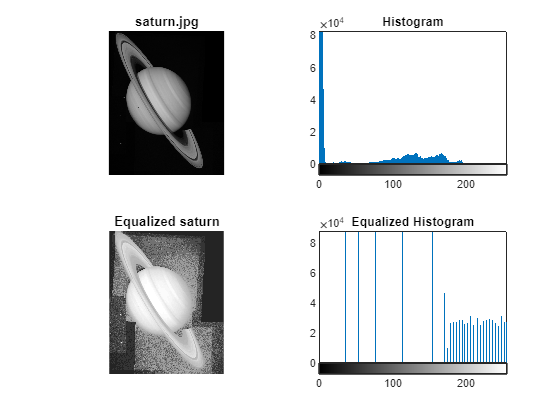

saturn = rgb2gray(imread('saturn.png'));
figure
subplot(2,2,1), imshow(saturn), title('saturn.jpg');
subplot(2,2,2), imhist(saturn), title('Histogram');
subplot(2,2,3), imshow(histeq(saturn)), title('Equalized saturn');
subplot(2,2,4), imhist(histeq(saturn)), title('Equalized Histogram');

Images with a lot of pixels with a similar gray level like in the saturn image will look strange when equalized becaus it adds too much contrast to areas with little variation.

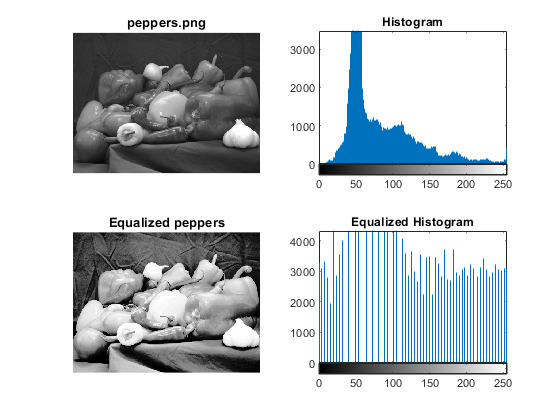

peppers = rgb2gray(imread('peppers.png'));
figure
subplot(2,2,1), imshow(peppers), title('peppers.png');
subplot(2,2,2), imhist(peppers), title('Histogram');
subplot(2,2,3), imshow(histeq(peppers)), title('Equalized peppers');
subplot(2,2,4), imhist(histeq(peppers)), title('Equalized Histogram');

The peppers image after equalization washes out the peppers and brightens the background a lot.

**3.**

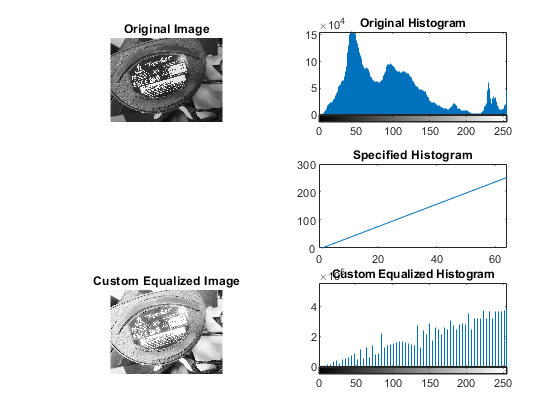

gress = rgb2gray(imread('gress.jpg'));
n = 64;
hgram = 0 : 256/n : 255;
HistEqImg = histeq(gress,hgram);
figure
subplot(3, 2, 1), imshow(gress), title('Original Image');
subplot(3, 2, 2), imhist(gress), title('Original Histogram');
subplot(3, 2, 4), plot(hgram), title('Specified Histogram');
subplot(3, 2, 5), imshow(HistEqImg), title('Custom Equalized Image');
subplot(3, 2, 6), imhist(HistEqImg,n), title('Custom Equalized Histogram');

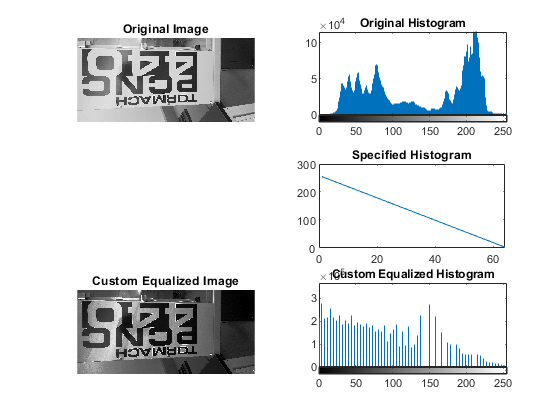

mill = rgb2gray(imread('mill.jpg'));
n = 64;
hgram = 255 : -256/n : 0;
HistEqImg = histeq(mill, hgram);
figure
subplot(3, 2, 1), imshow(mill), title('Original Image');
subplot(3, 2, 2), imhist(mill), title('Original Histogram');
subplot(3, 2, 4), plot(hgram), title('Specified Histogram');
subplot(3, 2, 5), imshow(HistEqImg), title('Custom Equalized Image');
subplot(3, 2, 6), imhist(HistEqImg, n), title('Custom Equalized Histogram');

The custom histograms do not enhance the readablity of the images. It just shifts the light areas and the dark areas.

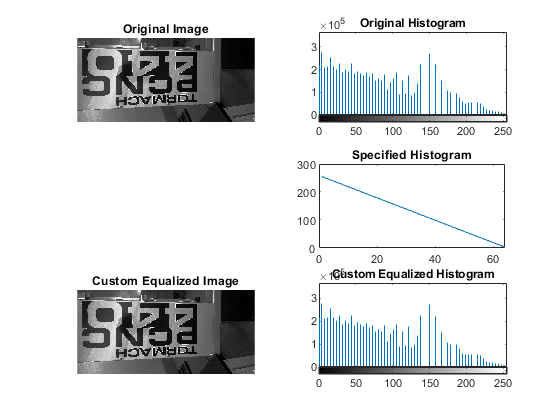

n = 64;
hgram = 255 : -256/n : 0;
HistEqImgAgain = histeq(HistEqImg, hgram);
figure
subplot(3, 2, 1), imshow(HistEqImg), title('Original Image');
subplot(3, 2, 2), imhist(HistEqImg, n), title('Original Histogram');
subplot(3, 2, 4), plot(hgram), title('Specified Histogram');
subplot(3, 2, 5), imshow(HistEqImgAgain), title('Custom Equalized Image');
subplot(3, 2, 6), imhist(HistEqImgAgain, n), title('Custom Equalized Histogram');

Equalizing an image twice does not produce a more equalized output.